# **Εργασία Τεχνικών Βελτιστοποίησης Part 1.**

### **Δημήτριος Μουταφτσίδης**

## **Εισαγωγή:**

Καλούμαστε να ελαχιστοποιήσουμε τρεις μονοδιάστατες συναρτήσεις σε δοσμένο διάστημα. Για την επίλυση του προβλήματος θα γίνει χρήση επαναληπτικών μεθόδων. Όλες οι μέθοδοι της άσκησης,πλην της 4ης, βασίζονται στο θεώρημα 5.1.1. του βιβλίου. Το θεώρημα αφορά αυστηρά σχεδόν-κυρτές συνάρτησεις. Η κύρια ιδέα τους αφορά τον κατ'εξακολούθηση περιοροσμό του διαστήματος αναζήτησης του ελαχίστου, εωσότου επιτευχθεί κάποια επιθυμητή ακρίβεια. Η ιδιότητα που χρειάζεται να συγκρατίσουμε είναι η ακόλουθη:

Για δίαστημα [a,b] και σημεία x1,x2 του διαστήματος με x1<x2

- αν f(x1)<f(x2), f(x)>=f(x1) για το διάστημα (x2,b]

- αν f(x1)>=f(x2), f(x)>=f(x2) για το διάστημα [a,x1)

Έτσι, αποκλείεται κάθε φορά ένα τμήμα του διαστήματος ως υποψήφιο για να περιέχει το ελάχιστο.

Ας ξεκινήσουμε με μία απεικόνιση των συναρτήσεων και υπολογισμό του ελαχίστου για την κάθε μία.

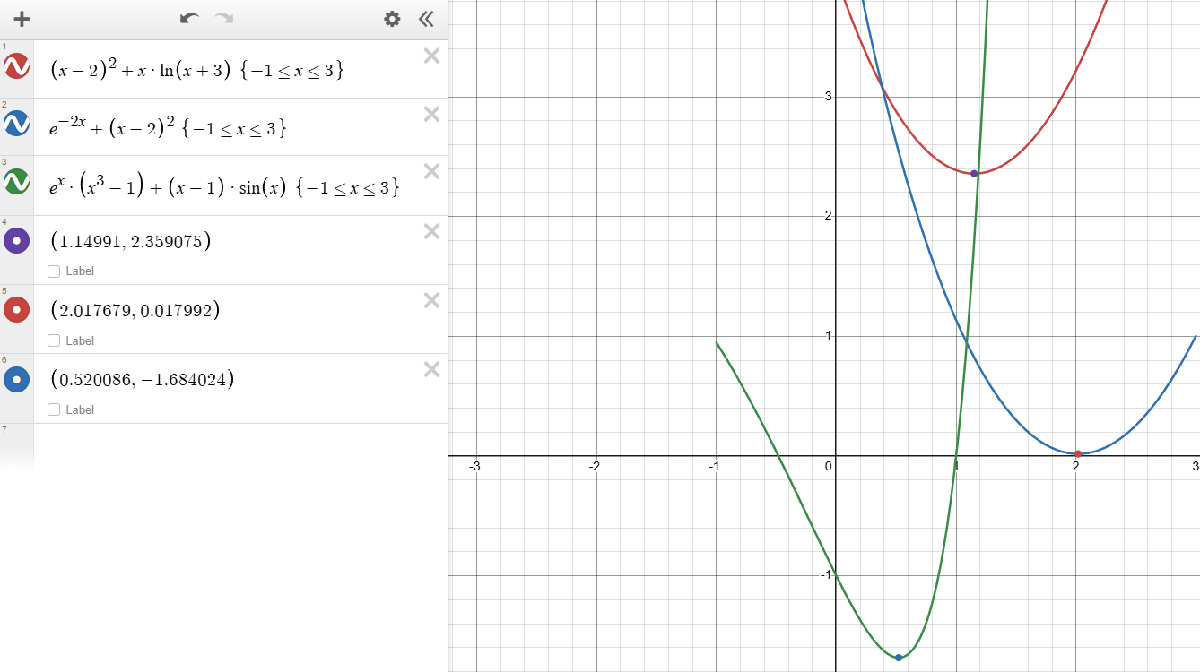

Από την μορφή τους καταλαβαίνουμε πως όλες πληρούν την προϋπόθεση περί κυρτότητας.

Η f1 εμφανίζει ελάχιστο στο x=1.14991, h f2 στο x=2.017679 και η f3 στο x=0.520086. Οι τιμές αυτές θα αποτελούν στο εξής κριτήριο ορθότητας των μεθόδων μας.

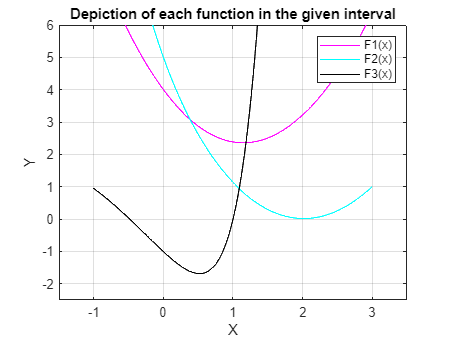

f1=@(x) (x-2).^2+x.*log(x+3);
f2=@(x) exp(-2.*x)+(x-2).^2;
f3=@(x) exp(x).*(x.^3-1)+(x-1).*sin(x);

x=linspace(-1,3,1000);

y1=f1(x);
y2=f2(x);
y3=f3(x);

figure(1);
plot(x,y1,'m',x,y2,'c',x,y3,'k');
title("Depiction of each function in the given interval");
xlabel("X");
ylabel("Y");
legend("F1(x)","F2(x)","F3(x)");
ylim([-2.5,6]);     %Αντιμετώπιση προβλημάτων κλίμακας.
xlim([-1.5,3.5]);
grid on;

Εισάγουμε τις συναρτήσεις στο Matlab και απεικονίζουμε ώστε να επιβεβαιώσουμε την ορθότητα. Τα αποτελέσματα φαίνονται ικανοποιητικά. 

## **Θέμα 1:**

Η πρώτη επαναληπτική μέθοδος που συναντάμε είναι αυτή της διχοτόμου. Είναι αρκετά απλή στη κατανόηση. Τίνει ,ωστόσο, να χρειάζεται αρκετούς υπολογισμούς της τιμής f(x) σε σχέση με τις υπόλοιπες μεθόδους. Δεν θα καταλάβουμε κάποια διαφορά στα πλαίσια αυτής της άσκησης. Κάτι τέτοιο όμως αποτελεί πρόβλημα σε πραγματικά προβλήματα βελτιστοποίσης, λόγω του υψηλού υπολογιστικού κόστους. Η διαδικασία ξεκινάει με την τοποθέτηση δύο βοηθητικών σημείων στο μέσο του διαστήματος σε απόσταση ε>0 έκαστο. Εξετάζεται η ιδίοτητα που προαναφέρθηκε και έτσι προκύπτει μικρότερο δίαστημα [x1,b] ή [a,x2] αντίστοιχα. Επαναλαμβάνουμε την τοποθέτηση και σύγκριση μέχρι ένα threshold l. Το έυρος του τελικού διαστήματος αποτελεί την ακρίβεια της μεθόδου μας. Λόγω της φύσης της μεθόδου, καταλαβαίνουμε πως ισχύει l<2ε.

function [an,bn,count,akvalues,bkvalues]= Bisector(f,e,l,a,b)

l and e must satisfy the condition l>2e.



The interval must be given in the form of [a,b], a<b.



    if a>=b
        fprintf("The interval must be given in the form of [a,b], a<b.\n\n");

For f1 the interval is [1.148827, 1.151315]. 



        return;
    end

For f2 the interval is [2.016557, 2.019045]. 




    if l<2*e

For f3 the interval is[0.518771, 0.521260]. 



        fprintf("l and e must satisfy the condition l>2e.\n\n")
        return;
    end
    if l<=0

The interval is expected to be less than 0.0025. For f1 it is 0.002488, for f2 it is 0.002488, for f3 it is 0.002488 



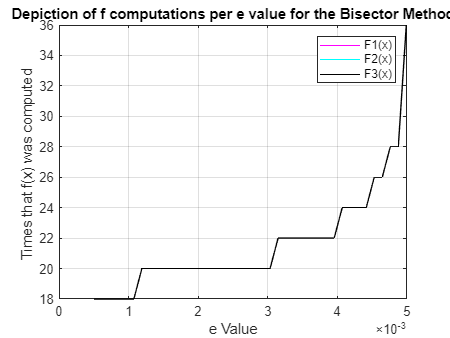

        fprintf("l must be positive.\n\n");
        return;
    end
    if e<=0
        fprintf("e must be positive.\n\n");
        return;
    end
    ak=a;
    bk=b;
    count=0;
    akvalues(count+1)=ak;
    bkvalues(count+1)=bk;
    while abs(ak-bk)>l
        count=count+1;

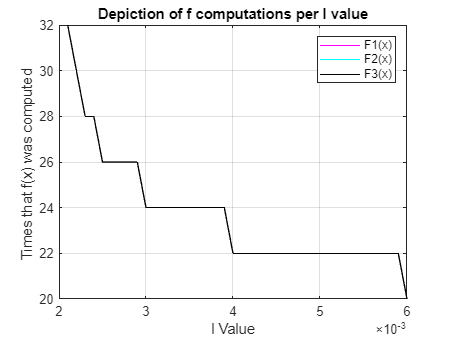

        x1k=(ak+bk)/2-e;
        x2k=(ak+bk)/2+e;
        if f(x1k)<f(x2k)
            bk=x2k;
        else
            ak=x1k;
        end
        akvalues(count+1)=ak;
        bkvalues(count+1)=bk;
    end
    an=ak;
    bn=bk;

end


Bisector(f1,0.01,0.01,-1,3);
Bisector(f2,0.001,0.0025,3,-1);
[a1,b1,~,~,~]=Bisector(f1,0.001,0.0025,-1,3);
fprintf("For f1 the interval is [%f, %f]. \n\n",a1,b1);
[a2,b2,~,~,~]=Bisector(f2,0.001,0.0025,-1,3);
fprintf("For f2 the interval is [%f, %f]. \n\n",a2,b2);
[a3,b3,~,~,~]=Bisector(f3,0.001,0.0025,-1,3);
fprintf("For f3 the interval is[%f, %f]. \n\n",a3,b3);
precisioncheck1=b1-a1;
precisioncheck2=b2-a2;
precisioncheck3=b3-a3;
fprintf("The interval is expected to be less than 0.0025. For f1 it is %f, for f2 it is %f, for f3 it is %f \n\n",precisioncheck1,precisioncheck2,precisioncheck3);

Παραπάνω βλέπουμε την συνάρτηση υλοποίησης της μεθόδου. Δέχεται ως ορίσματα μια συνάρτηση, το εύρος ε και την ακρίβεια l. Τα άκρα τους διαστήματος ,μόνο για αυτό το θέμα, αφέθηκαν επίσης στην επιλογή του χρήστη χάρην γενικότητας. Σε πρώτη φάση, η συνάρτηση πραγματοποιεί ελέγχους ορθότητας των ορισμάτων. Τυπώνει error message και τερματίζει πρόωρα σε περίπτωση λανθασμένης εισαγωγής ορισμάτων. Είναι ευθύνη του χρήστη,όμως, τα άκρα να ανήκουν στο πεδίο ορισμού, η ακρίβεια να μην είναι ευρύτερη από το διάστημα κ.α. Με την ολοκλήρωση τον παραπάνω,αχρικοποιούνται τα άκρα, καθώς και ένας μετρητής επαναλήψεων. Οι διαδοχικές τιμές που θα παίρνουν τα ak,bk αποθηκεύονται σε arrays, ώστε να αξιοποιηθούν στα ακόλουθα ερωτήματα.Η while loop που ακολουθεί, αποτελεί την "ψυχή" του αλγορίθμου. Εκτελείται μέχρι την επίτευξη της ακρίβειας. Τοποθετεί πρώτα τα βοηθητικά σημεία σε απόσταση ε εκατέροθεν του μέσου. Συνεχίζει συγκρίνοντας τις τιμές της f σε καθένα από αυτά. Στην συνέχια ενημερώνει τις τιμές των νέων ακρών κατάλληλα. Επαναλμβάνει υπλογίζοντας εκ νέου το μέσο και επανατοποθετώντας τα x1,x2. Μετά από κάθε if, οι επιλεγμένες τιμές αποθηκεύονται στους πίνακες akvalues,bkvalues. Μετά το πέρας της επαναλήψης, γίνεται variable assignment ,ώστε οι τιμές που επιστρέφονται να είναι η τελευταία ενημέρωση των άκρων. Η συνάρτηση καλείται ενδεικτικά για έλεγχο. Η ακρίβεια είναι ίδια για κάθε συνάρτηση. Να σημειώσουμε πως ο αιρθμός υπολογισμών τιμών της f(x) είναι διπλάσιος από τον αριθμό των επαναλήψεων. Σε κάθε loop η if statement υπολογίζει και τα δύο ώστε να κάνει την σύγκριση. Αυτό θα αξιοποιηθεί παρακάτω. Ακολουθεί το ερώτημα 1.

evalues=linspace(0.0005,0.00499,40);
[~,~,countvaluesf1]=arrayfun(@(e) Bisector(f1,e,0.01,-1,3),evalues);
[~,~,countvaluesf2]=arrayfun(@(e) Bisector(f2,e,0.01,-1,3),evalues);
[~,~,countvaluesf3]=arrayfun(@(e) Bisector(f3,e,0.01,-1,3),evalues);


figure(2);
plot(evalues,2*countvaluesf1,'m',evalues,2*countvaluesf2,'c',evalues,2*countvaluesf3,'k');
title("Depiction of f computations per e value for the Bisector Method");
xlabel("e Value");
ylabel("Times that f(x) was computed ");
legend("F1(x)","F2(x)","F3(x)");
grid on;

Καλούμε τρεις φορές την function, ώστε να εξάγουμε τον αριθμό υπολογισμών που χρειάζεται μέχρι τον τερματισμό για τις f1,f2,f3. Ορίζουμε το ε ως linspace. Παίρνει 40 διαφορετικές τιμές μεταξύ του 0.0005 και του 0.00499. Έπειτα plotάρουμε στο ίδιο διάγραμμα τον αριθμό επαναλήψεων που απαιτείται αυξανόμενου του ε. Πρώτη παρατήριση αποτελεί η ταύτιση των τριών διαγραμμάτων. Ο αριθμός υπολογισμών, επομένως, φαίνεται να εξαρτάται αποκλειστικά από το εύρος ε και όχι από την προς ελαχιστοποίηση συνάρτηση. Η αυξητική τάση του διαγράμματος είναι αναμενόμενη. Κάθως το εύρος ε μεγαλώνει, το "ψαλίδισμα" των διαστημάτων γίνεται με μικρότερο ρυθμό. Επομένως, για δεδομένη ακρίβεια χρειαζόμαστε περισσότερες επαναλήψεις, άρα και υπλλογισμούς. Η μορφή "σκάλας" είναι επίσης αξιοσημείωτη. Το εξηγούμε μέσω της διακριτής φύσης των επαναλήψεων. Κάθε σκάλι, μάλιστα, έχει ύψος δύο  ,αφού -όπως εξηγήσαμε προηγουμένως- κάθε iteration οδηγεί σε δύο υπολογισμούς. Όσον αφορά το διαρκώς μειούμενο πλατός, πρέπει να λάβουμε υπόψην την ακρίβεια. Ο αλγόριθμός μας έχει κάποια "ευαισθησία" σε μεταβολές του ε. Όσο μικρότερο είναι, τόσο λιγότερο ξεφεύγει κατά την μεταβολή του από το διάστημα ανοχής της ακρίβειας. Έτσι, για συγκεκριμένες τιμές του, πέφτουμε πάλι στο ίδιο δίαστημα και δεν απαιτείται εκ νέου επανάληψη (αδυνατώ να γίνω πιο κατανοητός).

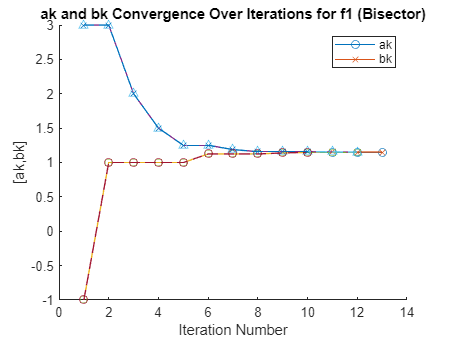

lvalues=linspace(0.0021,0.006,40);
[~,~,countvaluesf1]=arrayfun(@(l) Bisector(f1,0.001,l,-1,3),lvalues);
[~,~,countvaluesf2]=arrayfun(@(l) Bisector(f2,0.001,l,-1,3),lvalues);

[~,~,countvaluesf3]=arrayfun(@(l) Bisector(f3,0.001,l,-1,3),lvalues);


figure(3);
plot(lvalues,2*countvaluesf1,'m',lvalues,2*countvaluesf2,'c',lvalues,2*countvaluesf3,'k');
title("Depiction of f computations per l value");
xlabel("l Value");
ylabel("Times that f(x) was computed ");
legend("F1(x)","F2(x)","F3(x)");
grid on;

Για το δεύτερο ερώτημα ακολουθούμε αντίστοιχη διαδικασία. Κρατώντας το ε σταθερό, ορίζουμε το l ως linspace με 40 τιμές. Οι γραφικές παραστάσεις που προκύπτουν πάλι ταυτίζονται. Οδηγούμαστε ,λοιπόν, στο ίδιο συμπέρασμα και για το l. Η μορφή σκάλας διατηρείται.  Ο αριθμός των επαναλήψεων, ωστόσο, φθίνει αυξανομένου του l. Κάτι τέτοιο το αναμένουμε, αφού ελλατώνοντας την ακρίβεια, το εύρος της συνθήκης τερματισμού μεγαλώνει. Έτσι έχουμε γρηγορότερο πέρας του αλγορίθμου. (αναφορικά με το αυξανόμενο πλάτος των "σκαλοπατιών",  ομολογώ πως δεν έχω να προσφέρω κάποια αξιόλογη εξήγηση). Συνεχίζουμε με το τρίτο υποερώτημα.

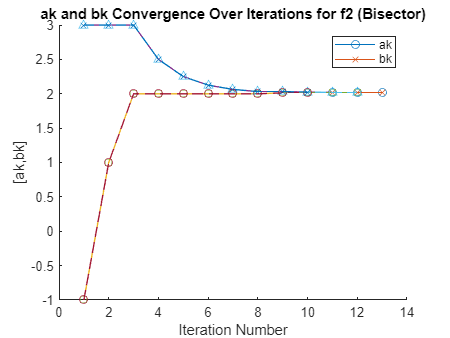

l1=0.003;
l2=0.004;
l3=0.005;
l4=0.01;

[~,~,~,akvalues1,bkvalues1]=Bisector(f1,0.001,l1,-1,3);
[~,~,~,akvalues2,bkvalues2]=Bisector(f1,0.001,l2,-1,3);
[~,~,~,akvalues3,bkvalues3]=Bisector(f1,0.001,l3,-1,3);
[~,~,~,akvalues4,bkvalues4]=Bisector(f1,0.001,l4,-1,3);
figure(4);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");


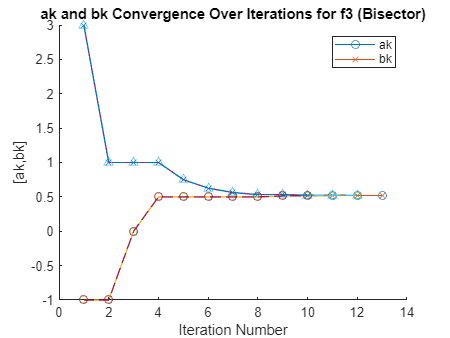

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f1 (Bisector)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");

[~,~,~,akvalues1,bkvalues1]=Bisector(f2,0.001,l1,-1,3);
[~,~,~,akvalues2,bkvalues2]=Bisector(f2,0.001,l2,-1,3);
[~,~,~,akvalues3,bkvalues3]=Bisector(f2,0.001,l3,-1,3);
[~,~,~,akvalues4,bkvalues4]=Bisector(f2,0.001,l4,-1,3);

figure(5);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");


plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f2 (Bisector)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");

[~,~,~,akvalues1,bkvalues1]=Bisector(f3,0.001,l1,-1,3);
[~,~,~,akvalues2,bkvalues2]=Bisector(f3,0.001,l2,-1,3);
[~,~,~,akvalues3,bkvalues3]=Bisector(f3,0.001,l3,-1,3);
[~,~,~,akvalues4,bkvalues4]=Bisector(f3,0.001,l4,-1,3);

figure(6);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f3 (Bisector)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");


Ο παραπάνω κώδικας υλοποιεί τα διαγράμματα του τρίτου ερωτήματος. Δημιουργείται ένα plot για κάθε συνάρτηση, το οποίο περιλαμβάνει τις καμπύλες σύγκλισης για τέσσερεις διαφορετικές τιμές του l. Παρατηρούμε πως οι τιμές των άκρων του διαστήματος εξαρτόνται μόνο από την εκάστοτε συνάρτηση. Το l δεν φαίνεται να επηρεάζει τον τρόπο σύγκλισης, καθώς οι καμπύλες ταυτίζονται. Τα [ak,bk] ξεκινούν από τα άκρα του αρχικού διαστήματος. Με κάθε επανάληψη έρχονται όλο και πιο κοντά στο τελικό interval που προσδιορίσαμε προηγουμένως. Να σημειώσουμε πως όταν ένα από τα ak,bk μεταβάλλονται, η τιμή του άλλου παραμένει σταθερή. Κάτι τέτοιο είναι αναμενόμενο, αφού ο αλγόριθμος τροποποιεί ένα από τα δύο κάθε φορά. Τέλος, απαιτείται ίδιος αιρμός επαναλήψεων για κάθε μία απο τις τρείς συναρτήσεις

## **Θέμα 2:**

Η δεύτερη μέθοδος είναι αυτή του χρυσού τομέα. Η λογική της δεν διαφέρει ιδιαίτερα απο αυτή της Διχοτόμου. Αξιοποιείται πάλι η ιδιότητα των αυστηρά σχεδόν-κυρτών συναρτήσεων. Το επόμενο κατά σειρά υποδιάστημα υπολογίζεται με πολλαπλασιασμό του προηγούμενου με μία σταθερά γ=0.618. Τα βοηθητικά σημεία υπολογίζονται ως εξής:  

- x1k= ak+(1-γ)(bk-ak)

- x2k=ak+γ(bk-ak)

Για f(x1k)>f(x2k) ορίζουμε ως νέο υποδιάστημα το [x1k,bk]. Σε αντίθετη περίπτωση, ορίζουμε το [ak,x2k]. Επαναλαμβάνουμε έως την επίτευξη της επιθυμητής ακρίβειας. Βασικό πλεονέκτημα της μεθόδου αποτελεί ο σημαντικά μικρότερος αριθμός υπολογισμών της f απαιτούνται. Η συνάρτηση υπολογίζεται δύο φορές μόνο στην πρώτη εκτέλεση. Στην συνέχεια, λόγω της ταύτισης ενός από τα επόμενα βοηθητικά σημεία με ένα από τα προηγούμενα, χρειάζεται μόνο ένας υπολογισμός. Περισσότερες λεπτομέρειες θα δωθούν κατά την περιγραφή του αλγορίθμου

function[ak,bk,iterations,akvalues,bkvalues]=GoldenSector(f,l)

l must be positive. 




    ak=-1;
    bk=3;
    c=0.618;
    iterations=1;

For f1 the interval is [1.149856, 1.149926]. 



    x1=ak+(1-c)*(bk-ak);

For f2 the interval is [2.017633, 2.017732]. 



    x2=ak+c*(bk-ak);

For f3 the interval is [0.520023, 0.520103]. 



    akvalues(iterations)=ak;
    bkvalues(iterations)=bk;
    f1=f(x1);
    f2=f(x2);
    if l<=0

The interval is expected to be less than 0.0001. For f1 it is 0.000070, for f2 it is 0.000099, for f3 it is 0.000080 



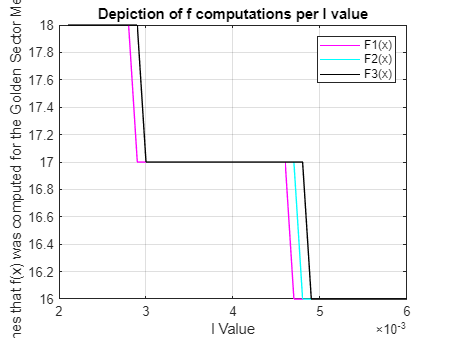

        fprintf("l must be positive. \n\n")
        return;
    end
    while(bk-ak>l)
        iterations=iterations+1;
        if f1>f2
            ak=x1;
            x1=x2;
            f1=f2;
            x2=ak+c*(bk-ak);
            f2=f(x2);
        else    
            bk=x2;
            x2=x1;

            f2=f1;
            x1=ak+(1-c)*(bk-ak);
            f1=f(x1);
        end
        akvalues(iterations)=ak;
        bkvalues(iterations)=bk;
    end
end

GoldenSector(f1,-2);
[a1,b1]=GoldenSector(f1,0.0001);
[a2,b2]=GoldenSector(f2,0.0001);
[a3,b3]=GoldenSector(f3,0.0001);

fprintf("For f1 the interval is [%f, %f]. \n\n",a1,b1);
fprintf("For f2 the interval is [%f, %f]. \n\n",a2,b2);
fprintf("For f3 the interval is [%f, %f]. \n\n",a3,b3);

precisioncheck1=b1-a1;
precisioncheck2=b2-a2;
precisioncheck3=b3-a3;
fprintf("The interval is expected to be less than 0.0001. For f1 it is %f, for f2 it is %f, for f3 it is %f \n\n",precisioncheck1,precisioncheck2,precisioncheck3);

.Ο παραπάνω κώδικας υλοποιεί την Μέθοδο του Χρυσού Τομέα. Η συνάρτηση δέχεται ως ορίσματα μία συνάρτηση f και την ακρίβεια l. Δίνονται αρχικά οι τιμές του διαστήματος, μετά από έλεγχο ορθότητας για το l. Αρχικοποιούνται επίσης η σταθερά γ, ένας δείκτης για τον αριθμό των επαναλήψεων και δύο πίνακες για την αποθήκευση των τιμών των άκρων. Τα βοηθητικά σημεία λαμβάνουν επίσης τις αρχικές τους τιμές και υπολογίζονται οι τιμές της f σε αυτά . Ο αλγόριθμος περιλαμβάνει πάλι μία while loop. Εκτελείται μέχρι το διάστημα να ικανοποιεί την επιθυμητή ακρίβεια. Εντός της, η if statement συγκρίνει τις f(x1k),f(x2k). Σε κάθε case γίνονται τα κατάλληλα variable assigments. Τα νέα διαστήματα ορίζονται ως [x1k,bk] στην πρώτη και [ak,x2k] στην δεύτερη. Εδώ εντοπίζεται και το πλεονέκτημα της μεθόδου. Λόγω του assignment x1k+1=x2k / x2k+1=x1k μπορούμε μέσω δεύτερου assignment να αναθέσουμε τιμή στο f(x1k+1)/f(x2k+1). Έτσι, ο συνολικός αριθμός υπολογισμών της f θα είναι (αριθμός επαναλήψεων+1). Τέλος, η συνάρτηση επιστρέφει το τελικό διάστημα, τον συνολικό αριθμό επαναλήψεων που χρειάστηκαν και τους πίνακες τιμών των ak,bk. Γίνεται δοκιμαστική κλίση για έλεγχο ορθότητας του κώδικα.

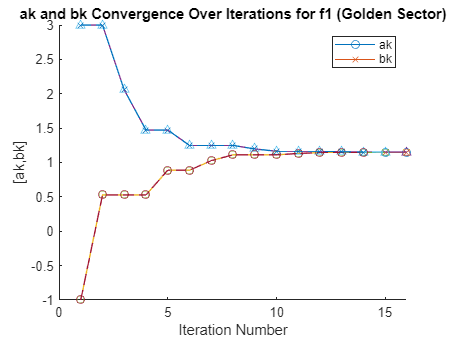

lvalue=linspace(0.0021,0.006,40);

[~,~,iterationsf1]=arrayfun(@(l) GoldenSector(f1,l),lvalue);
[~,~,iterationsf2]=arrayfun(@(l) GoldenSector(f2,l),lvalue);
[~,~,iterationsf3]=arrayfun(@(l) GoldenSector(f3,l),lvalue);

figure(7);
plot(lvalue,1+iterationsf1,'m',lvalue,1+iterationsf2,'c',lvalue,1+iterationsf3,'k');

title("Depiction of f computations per l value");
xlabel("l Value");
ylabel("Times that f(x) was computed for the Golden Sector Method");
legend("F1(x)","F2(x)","F3(x)");
grid on;

Για το πρώτο ερώτημα δημιουργούμε linspace για το l, ίδιο με αυτό του πρώτου ερωτήματος. Το διάγραμμα που προκύπτει έχει παρόμοια μορφή. Ο αριθμός τον υπολογισμών είναι σημαντικά μικρότερος από αυτόν της μεθόδου της Διχοτόμου. Παρατηρούμε επίσης μεγαλύτερο εύρος σε κάθε "σκαλοπάτι". Οι γραφικές παραστάσεις φαίνεται να διαφέρουν σε ορισμένα σημεία. Κάτι τέτοιο δεν χρίζει απαραίτητα αξιολόγισης. Οι τιμές του l είναι πολύ μικρές και θα μπορούσαν να οφείλονται σε σφάλματα σχετικά με το πως επεξεργάζεται τα floating points ο υπολογιστής.

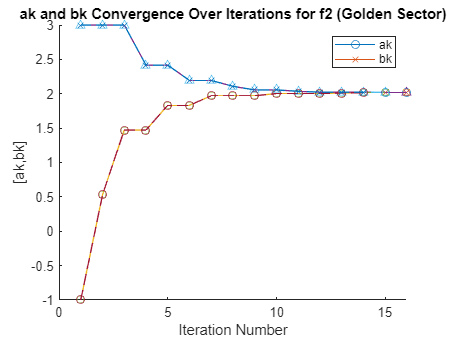

l1=0.003;
l2=0.004;
l3=0.005;
l4=0.01;

[~,~,~,akvalues1,bkvalues1]=GoldenSector(f1,l1);
[~,~,~,akvalues2,bkvalues2]=GoldenSector(f1,l2);
[~,~,~,akvalues3,bkvalues3]=GoldenSector(f1,l3);
[~,~,~,akvalues4,bkvalues4]=GoldenSector(f1,l4);

figure(8);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");

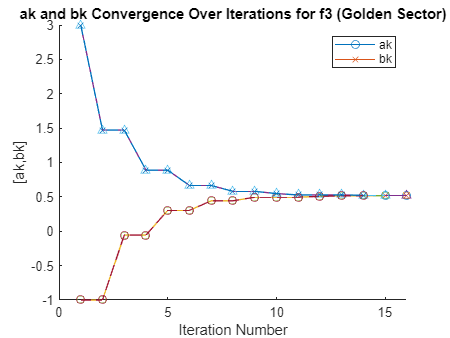

plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f1 (Golden Sector)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");

[~,~,~,akvalues1,bkvalues1]=GoldenSector(f2,l1);
[~,~,~,akvalues2,bkvalues2]=GoldenSector(f2,l2);
[~,~,~,akvalues3,bkvalues3]=GoldenSector(f2,l3);
[~,~,~,akvalues4,bkvalues4]=GoldenSector(f2,l4);

figure(9);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");

plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f2 (Golden Sector)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");

[~,~,~,akvalues1,bkvalues1]=GoldenSector(f3,l1);
[~,~,~,akvalues2,bkvalues2]=GoldenSector(f3,l2);
[~,~,~,akvalues3,bkvalues3]=GoldenSector(f3,l3);
[~,~,~,akvalues4,bkvalues4]=GoldenSector(f3,l4);

figure(10);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f3 (Golden Sector)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");

Ο σχολιασμός και η υλοποίηση είναι όμοιος με αυτόν του προηγούμενου θέματος. Παρατηρούμε ωστόσο πως παρόλο που ο αριθμός υπολογισμών είναι μικρότερος, η Μέθοδος του Χρυσού Τομέα χρειάζεται περισσότερες επαναλήψεις για την ίδια ακρίβεια.

## **Θέμα 3:**

Η μέθοδος Fibonacci αποτελεί μια δυναμική εκδοχή αυτής του Χρυσού Τομέα. Αντί της σταθεράς γ, γίνεται χρήση μεταβαλλόμενου λόγου αριθμών Fibonacci για τον σταδιακό περιορισμό του εύρους του διαστήματος. Συγκεκριμένα, τα βοηθητικά σημεία ορίζονται ως x1k=ak+(Fn-k-1/Fn-k+1)*(bk-ak) και x2k=ak+(Fn-k/Fn-k+1)*(bk-ak). Καταλαβαίνουμε λοιπόν πως λόγω της εξάρτησης των συντελεστών F από τον αριθμό της επανάληψης, ο λόγος τους μεταβάλλεται συνεχώς. Ορίζουμε το νέο υποδιάστημα ως [x1k,bk] ή [ak,x2k] για f(x1k)>f(x2k) και f(x1k)<f(x2k) αντίστοιχα. Το k+1 διάστημα συνδέται με το k ως εξής: (bk+1-ak+1)=(Fn-k-2/Fn-k)*(bk-ak). Μειώνεται δηλαδή με μη σταθερό ρυθμό. Ένα από τα πλεονεκτήματα της μεθόδου, είναι η ταύτιση του xk+1 με το x2k για την πρώτη περίπτωση και του x2k+1 με το x1k για την δεύτερη. Έτσι, όπως είδαμε και στην μέθοδο του Χρυσού Τομέα, απαιτείται μόνο ένας εκ νέου υπολογισμός της  f(x). Μία ιδιαιτερότητα της μεθόδου, είναι η ανάγκη για προκαθορισμένο αριθμό επαναλήψεων n-1. Για τον υπολογισμό του n, επιλύουμε την ανισότητα Fn>b1-a1/l, όπoυ l η επιθυμητή ακρίβεια. Όσο μικρότερο είναι το διάστημα ανοχής, τόσο μεγαλύτερο αριθμό επαναλήψεων θα χρειαστούμε. Ας δούμε τον αλγόριθμο υλοποιημένο σε κώδικα.

function[iterations,a,b]=FibonacciMethod(f,e,l)

e must be positive.




    a(1)=-1;
    b(1)=3;
    n=1;
    iterations=1;
    fib=fibonacci(1);

For f1 the interval is [1.147059,1.150155]



For f2 the interval is [2.017028,2.020123]



    if l<=0

For f3 the interval is [0.518576,0.520124]



        fprintf("l must be positive.\n\n");
        return;
    end
    
    if e<=0
        fprintf("e must be positive.\n\n");

The interval is expected to be less than 0.004. For f1 it is 0.003096, for f2 it is 0.003096, for f3 it is 0.001548 



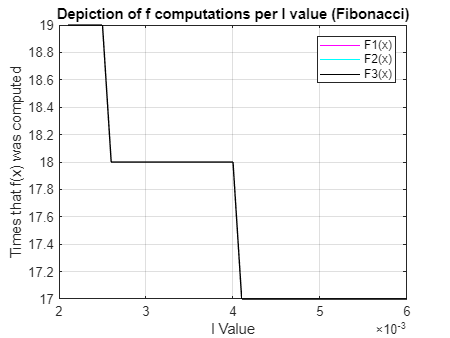

        return;
    end
    
    while fib<(b(1)-a(1))/l
        n=n+1;
        fib=fibonacci(n);
    end

    %fprintf("The value for n is %d for the given precision\n\n",n);

    fiblist=zeros(n);

    for i=1:n+1
        fiblist(i)=fibonacci(i);
    end


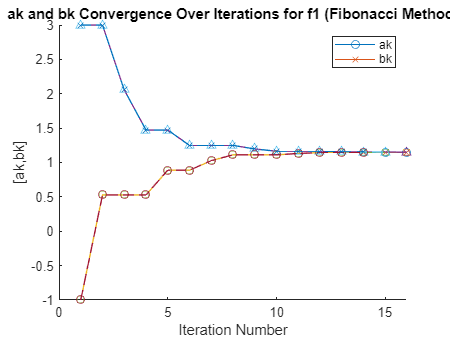

    %fprintf("%g",fiblist); 

    x1=a(1)+(fiblist(n-2)/fiblist(n))*(b(1)-a(1));
    x2=a(1)+(fiblist(n-1)/fiblist(n))*(b(1)-a(1));

    f1=f(x1);
    f2=f(x2);

    k=1;

    while (b(k)-a(k))>l
        iterations=iterations+1;
        if f1>f2
            a(k+1)=x1;
            b(k+1)=b(k);
            x1=x2;
            f1=f2;
            x2=a(k+1)+(fiblist(n-k)/fiblist(n-k+1))*(b(k+1)-a(k+1));
            f2=f(x2);
        else
            a(k+1)=a(k);
            b(k+1)=x2;
            x2=x1;
            f2=f1;
            x1=a(k+1)+(fiblist(n-k-1)/fiblist(n-k+1))*(b(k+1)-a(k+1));
            f1=f(x1);
        end

        if k==n-2
            x2=x1+e;

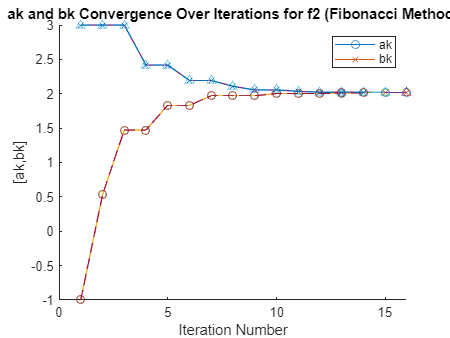

            f2=f(x2);
            if f1>f2
                a(n-1)=x1;
                b(n-1)=b(n-2);
            else 
                a(n-1)=a(n-2);
                b(n-1)=x1;
            end
        %fprintf("Iterations: %d\n\n",iterations);
        return;
        else
            k=k+1;
        end
            

    end
%fprintf("Iterations: %d\n\n",iterations);    

end
    
FibonacciMethod(f1,-1,2);

[iterations1,a1,b1]=FibonacciMethod(f1,0.001,0.004);
[iterations2,a2,b2]=FibonacciMethod(f2,0.001,0.004);
[iterations3,a3,b3]=FibonacciMethod(f3,0.001,0.004);


fprintf("For f1 the interval is [%f,%f]\n\n",a1(iterations1),b1(iterations1));
fprintf("For f2 the interval is [%f,%f]\n\n",a2(iterations2),b2(iterations2));
fprintf("For f3 the interval is [%f,%f]\n\n",a3(iterations2),b3(iterations3));

precisioncheck1=b1(iterations1)-a1(iterations1);
precisioncheck2=b2(iterations2)-a2(iterations2);
precisioncheck3=b3(iterations3)-a3(iterations3);

fprintf("The interval is expected to be less than 0.004. For f1 it is %f, for f2 it is %f, for f3 it is %f \n\n",precisioncheck1,precisioncheck2,precisioncheck3);


Σχόλιο: Η υλοποίηση της μεθόδου ήταν για εμένα αισθητά πολυπλοκότερη. Αντιμετώπισα προβλήματα στο indexing των πινάκων, τα οποία έλυσα με πειραματισμό. Εν τέλει ο αλγόριθμος του βιβλίου φαίνεται να ικανοποιείται. Ενδεχομένως ωστόσο να παρέχω μία υποβέλτιστη λύση. Τα commented lines στον κώδικα χρησιμοποιήθηκαν για debugging.

Η συνάρτηση καλείται με ορίσματα την f, το διάστημα ε και την ακρίβεια l. Επιστρέφει πίσω τον αριθμό των επαναλήψεων και δύο πίνακες με τις δίαφορες τιμές των ak,bk. Το τελικό διάστημα θα βρίσκεται στην iterations θέση των πινάκων αυτών, με βάση το πως τα έχουμε ορίσει. Μετά την αρχικοποίηση των άκρων του διαστήματος και των δεικτών n και iterations, η συνάρτησει πραγματοποιεί ελέγχους ορθότητας. Έπειτα, μέσω της προσωρινής μεταβλητής fib και μιας while loop καθορίζεται ο αριθμός n. Οι n αριθμοί Fibonacci αποθηκεύονται σε λίστα, ώστε να μην χρειάζεται ο εκ νέου υπολογισμός τους. Γίνεται χρήση της built-in συνάρτησης fibonacci. Στην συνέχεια, υπολογίζονται τα πρώτα βοηθητικά σημεία και οι τιμές της f σε αυτά. Παρόλο που ο προκαθορισμένος αριθμός επανλήψεων παραπέμπει σε for, επιλέχθηκε while loop για την υλοποίηση των επαναλήψεων. Ο αλγόριθμος ,άλλωστε, τερματίζει για n-1 επαναλήψεις λόγω της ύπαρξης return εντός ενός από τα if statements. Εντός του loop, γίνεται σύγκριση των f(x1k),f(x2k) και γίνονται οι κατάλληλες αναθέσεις σύμφωνα με το βιβλίο. Παρατηρούμε πως σε κάθε loop, πλήν του τελευταίου κατά το οποίο ενεργοποιείται και το δεύτερο if, γίνεται ένας μόνο υπολογισμός της συνάρτησης. Η ταύτιση ενός βοηθητικού σημείου με προηγούμενο καλύπτει την ανάγκη για δεύτερο υπολογισμό μέσω assignment. Η ενεργοποίση της δεύτερης if σηματοδοτεί το πέρας του αλγορίθμου. Όταν ο δείκτης k γίνει ίσος με n-2, υπολογίζονται για τελευταία φορά τα βοηθητικά σημεία με χρήση του ε και οι πίνακες τιμών των a,b λαμβάνουν την τελική τους τιμή. Ο συνολικός αριθμός υπολογισμών της f λοιπόν, δίνεται από την σχέση αριθμός επαναλήψεων+2.

lvalue=linspace(0.0021,0.006,40);

[iterationsf1]=arrayfun(@(l) FibonacciMethod(f1,0.001,l),lvalue);
[iterationsf2]=arrayfun(@(l) FibonacciMethod(f2,0.001,l),lvalue);
[iterationsf3]=arrayfun(@(l) FibonacciMethod(f3,0.001,l),lvalue);

figure(11);
plot(lvalue,2+iterationsf1,'m',lvalue,2+iterationsf2,'c',lvalue,2+iterationsf3,'k');
title("Depiction of f computations per l value (Fibonacci)");
xlabel("l Value");
ylabel("Times that f(x) was computed");
legend("F1(x)","F2(x)","F3(x)");
grid on;

Το διάγραμμα που προκύπτει Μοιάζει πολύ με αυτό του Χρυσού Τομέα. Είναι αυτό που περιμέναμε. Τα διαγράμματα ταυτίζονται απόλυτα και η μορφή "σκάλας" παραμένει. Ο σχολιασμός που έγινε σε προηγούμενα αντίστοιχα ερωτήματα είναι επαρκής.

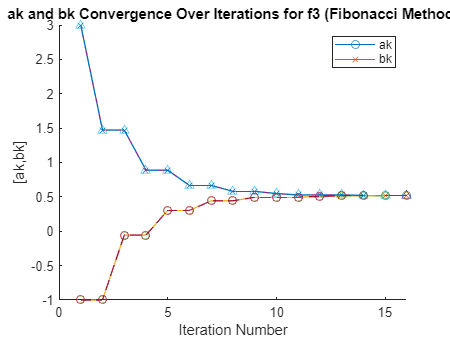

l1=0.003;
l2=0.004;
l3=0.005;
l4=0.01;


[~,akvalues1,bkvalues1]=FibonacciMethod(f1,0.001,l1);
[~,akvalues2,bkvalues2]=FibonacciMethod(f1,0.001,l2);
[~,akvalues3,bkvalues3]=FibonacciMethod(f1,0.001,l3);
[~,akvalues4,bkvalues4]=FibonacciMethod(f1,0.001,l4);

figure(12);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f1 (Fibonacci Method)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");


[~,akvalues1,bkvalues1]=FibonacciMethod(f2,0.001,l1);
[~,akvalues2,bkvalues2]=FibonacciMethod(f2,0.001,l2);
[~,akvalues3,bkvalues3]=FibonacciMethod(f2,0.001,l3);
[~,akvalues4,bkvalues4]=FibonacciMethod(f2,0.001,l4);

figure(13);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f2 (Fibonacci Method)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");




l must be positive



[~,akvalues1,bkvalues1]=FibonacciMethod(f3,0.001,l1);
[~,akvalues2,bkvalues2]=FibonacciMethod(f3,0.001,l2);
[~,akvalues3,bkvalues3]=FibonacciMethod(f3,0.001,l3);
[~,akvalues4,bkvalues4]=FibonacciMethod(f3,0.001,l4);


For f1 the interval is [1.149910, 1.149918]. 



figure(14);

For f2 the interval is [2.017677, 2.017685]. 



hold on;

For f3 the interval is [0.520081, 0.520088]. 



plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

The interval is expected to be less than 0.00001. For f1 it is 0.000008, for f2 it is 0.000008, for f3 it is 0.000008 




plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f3 (Fibonacci Method)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");


Παρατηρούμε για ακόμα μια φορά πως τα διαγράμματα για διάφορες τιμές του l και σταθερό ε ταυτίζονται. Ο αριθμός επαναλήψεων είναι ίδιος με αυτόν του Χρυσού Τομέα. Αν προσέξουμε μάλιστα ένα προς ένα τα γραφήματα για την κάθε συνάρτηση, διαπιστώνουμε πως ο τρόπος σύγκλισης μοιάζει, έως και ταυτίζεται. Γνωρίζουμε άλλωστε από την θεωρία, πως καθώς το n αυξάνεται ο όρος των Fibonacci αριθμών συγκλίνει στην τιμή του γ. Μία τέτοια παρατήριση ,λοιπόν, δεν μας προκαλεί εντύπωση.

## **Θέμα 4:**

Η μέθοδος Διχοτόμου με Χρήση Παραγώγων είναι η πρώτη μέθοδος που δεν βασίζεται στην ιδιότητα 5.1.1. Για το περιορισμό του διαστήματος υποθέτουμε κυρτότητα και εξετάζουμε την τιμή της παραγώγου στο βοηθητικό σημείο. Για μηδενική παράγωγο, έχουμε ήδη προσδιορίσει το ελάχιστο. Δεν απαιτούνται περεταίρω ενέργειες. Το σενάριο αυτό ωστόσο είναι αρκετά απίθανο. Για θετική παράγωγο στο xk, αναμένουμε την f αυξάνει, οπότε δεν έχει νόημα να αναζητούμε δεξιότερά του. Περιορίζουμε λοιπόν το διάστημα στο [ak,xk]. Σε αντίθετη περίπτωση, αναζητούμε πλέον στο [xk,bk]. Η μέθοδος απαιτεί την χρήση ενός μόνο βοηθητικού σημείου, το οποίο τοποθετείται στο κέντρο του διαστήματος. Έτσι, ο αλγόριθμος που την περιγράφει είναι σχετικά απλός και κατανοητός. Απαιτεί επίσης προκαθορισμένο αριθμό επαναλήψεων. Για τον προσδιορισμό του επιλύουμε την σχέση (1/2)^n<= l(b1-a1), όπου l η επιθυμητή ακρίβεια. Επιλέγουμε τον μικρότερο ακέραιο που την ικανοποιεί.Nα σημειώσουμε πως βασικό μειονέκτημα της μεθόδου είναι η απαίτηση για διαφορίσιμη f, τουλάχιστον στο διάστημα ενδιαφέροντος. Σε πραγματικά σενάρια, κάτι τέτοιο δεν αποτελεί κανόνα. Ας υλοποιήσουμε σε κώδικα.

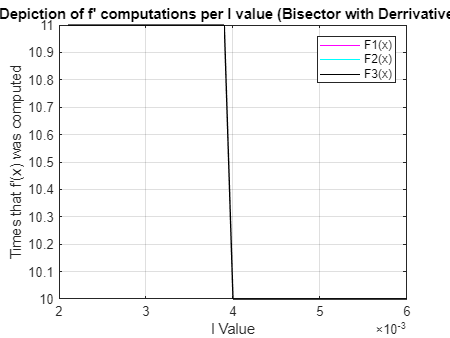

function[ak,bk,iterations,avalues,bvalues]=BisectorDif(f,l)

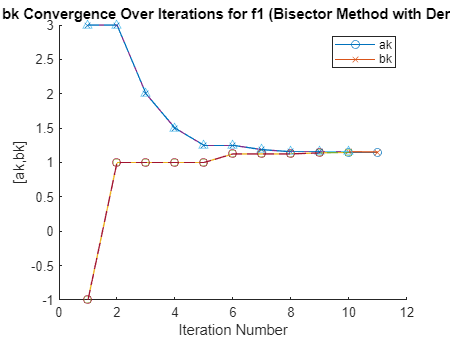


    ak=-1;
    bk=3;
    iterations=0;
    n=1;
    
    if l<=0
        fprintf("l must be positive\n\n");
        return;
    end
    syms x
    fs=f(x);
    fder=diff(fs,x);
    fderh=matlabFunction(fder);

    while 0.5^n>l/(bk-ak)
        n=n+1;
    end

    xk=(bk+ak)/2;
    %avalues=zeros(n);
    %bvalues=zeros(n);
    %avalues(1)=ak;
    %bvalues(1)=bk;
 

    for k=1:n
        avalues(k)=ak;
        bvalues(k)=bk;
        iterations=iterations+1;

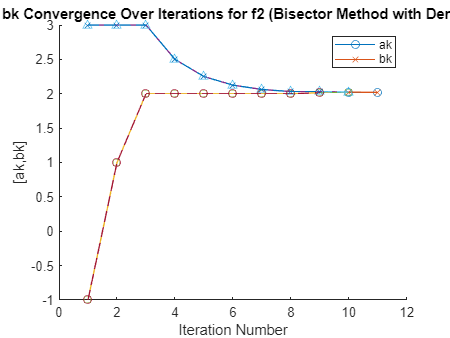

        fvalue=fderh(xk);
        if fvalue==0
            return;
        elseif fvalue>0
            bk=xk;
        else 
            ak=xk;
        end
        xk=(bk+ak)/2;
        
    end    
    %if n~=iterations; fprintf("Error Message\n\n"); end
    %fprintf("n=%d , iterations=%d\n\n",n,iterations);


end

BisectorDif(f1,-2);
[a1,b1]=BisectorDif(f1,0.00001);
[a2,b2]=BisectorDif(f2,0.00001);
[a3,b3]=BisectorDif(f3,0.00001);

fprintf("For f1 the interval is [%f, %f]. \n\n",a1,b1);
fprintf("For f2 the interval is [%f, %f]. \n\n",a2,b2);
fprintf("For f3 the interval is [%f, %f]. \n\n",a3,b3);


precisioncheck1=b1-a1;
precisioncheck2=b2-a2;
precisioncheck3=b3-a3;
fprintf("The interval is expected to be less than 0.00001. For f1 it is %f, for f2 it is %f, for f3 it is %f \n\n",precisioncheck1,precisioncheck2,precisioncheck3);

Η συνάρτησή μας δέχεται ως όρισμα την f και την τιμή για το l. Γίνονται οι συνήθεις αρχικοποιήσεις και έλεγχοι ορθότητας. Ακολούθως, υπολογίζεται η παράγωγος της f και μετατρέπεται εκ νέου σε συνάρτηση. Μέσω της while προσδιορίζεται το n και γίνεται preallocation για τους πίνακες τιμών των άκρων κατά τα συνηθισμένα. Αφού αρχικοποιηθεί το βοηθητικό σημείο ξεκινάει η for loop. Εντώς αυτής ,σε κάθε επανάληψη, υπολογίζεται η τιμή της παραγώγου στο xk. Γίνονται στην συνέχεια οι συγκρίσεις μέσω της if καθώς και τα κατάλληλα variable assignments ανάλογα με την περίπτωση. Το iteration counter  και οι akvalues,bkvalues πίνακες ενημερώνονται. Για k=n ο αλγόριθμος τερματίζει. Παρατηρούμε πως σε κάθε επανάληψη απαιτείται ένας και μόνο υπολογισμός τιμής συνάρτησης. Η μέθοδος είναι γενικά απλή, κατανοητή και με χαμηλό υπολογιστικό κόστος.

lvalue=linspace(0.0021,0.006,40);

[~,~,iterationsf1]=arrayfun(@(l) BisectorDif(f1,l),lvalue);
[~,~,iterationsf2]=arrayfun(@(l) BisectorDif(f2,l),lvalue);
[~,~,iterationsf3]=arrayfun(@(l) BisectorDif(f3,l),lvalue);

figure(15);
plot(lvalue,iterationsf1,'m',lvalue,iterationsf2,'c',lvalue,iterationsf3,'k');
title("Depiction of f' computations per l value (Bisector with Derrivatives)");
xlabel("l Value");
ylabel("Times that f'(x) was computed");
legend("F1(x)","F2(x)","F3(x)");
grid on;

Η μορφή είναι αυτή που περιμέναμε. Παρατηρούμε πλήρη ταύτιση των παραστάσεων. Τα σκαλοπάτια έχουν μεγάλο πλάτος. Το γεγονός αυτό μαρτυρά αυξημένη ανοχή σε μεταβολές τιμών του l. Η μέθοδος απαιτεί αισθητά λιγότερους υπολογισμούς της f'(x).

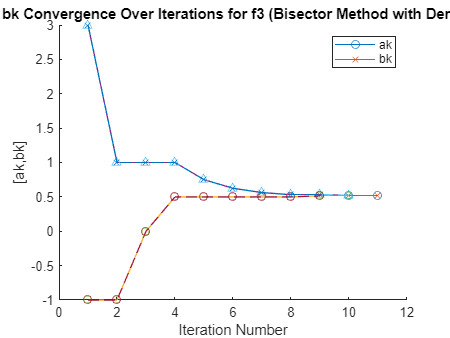

l1=0.003;
l2=0.004;
l3=0.005;
l4=0.01;

[~,~,~,akvalues1,bkvalues1]=BisectorDif(f1,l1);
[~,~,~,akvalues2,bkvalues2]=BisectorDif(f1,l2);
[~,~,~,akvalues3,bkvalues3]=BisectorDif(f1,l3);

[~,~,~,akvalues4,bkvalues4]=BisectorDif(f1,l4);

figure(16);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f1 (Bisector Method with Derrivatives)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");


[~,~,~,akvalues1,bkvalues1]=BisectorDif(f2,l1);
[~,~,~,akvalues2,bkvalues2]=BisectorDif(f2,l2);
[~,~,~,akvalues3,bkvalues3]=BisectorDif(f2,l3);
[~,~,~,akvalues4,bkvalues4]=BisectorDif(f2,l4);

figure(17);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f2 (Bisector Method with Derrivatives)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");


[~,~,~,akvalues1,bkvalues1]=BisectorDif(f3,l1);
[~,~,~,akvalues2,bkvalues2]=BisectorDif(f3,l2);
[~,~,~,akvalues3,bkvalues3]=BisectorDif(f3,l3);
[~,~,~,akvalues4,bkvalues4]=BisectorDif(f3,l4);

figure(18);
hold on;
plot(1:length(akvalues1),akvalues1,'-o','DisplayName',"Values of ak for l1");
plot(1:length(bkvalues1),bkvalues1,'-x','DisplayName',"Values of bkcfor l1");

plot(1:length(akvalues2),akvalues2,'-s','DisplayName',"Values of ak for l2");
plot(1:length(bkvalues2),bkvalues2,'-^','DisplayName',"Values of bkcfor l2");

plot(1:length(akvalues3),akvalues3,'--s','DisplayName',"Values of ak for l3");
plot(1:length(bkvalues3),bkvalues3,'--^','DisplayName',"Values of bkcfor l3");

plot(1:length(akvalues4),akvalues4,'--o','DisplayName',"Values of ak for l4");
plot(1:length(bkvalues4),bkvalues4,'--x','DisplayName',"Values of bkcfor l4");
hold off;

title("ak and bk Convergence Over Iterations for f3 (Bisector Method with Derrivatives)");
xlabel("Iteration Number");
ylabel("[ak,bk]");
legend("ak","bk");

H σύγκλιση φαίνεται να είναι ανεξάρτητη του l για ακόμια μία φορά. Παρατηρούμε πως για κάθε συνάρτηση, το γενικό σχήμα των διαγραμμάτων μοιάζει. Αυτό ίσως εξηγείται από την παρόμοια μορφή που έχουν στο επίπεδο.

## **Γενικά Σχόλια:**

Η μέθοδος της διχοτόμου είναι απλή αλγοριθμικά και εύκολη στην κατανόηση και εφαρμογή. Ενδείκνυται για απλές συναρτήσεις f, καθώς τίνει να χρειάζεται μεγάλο αριθμό υπολογισμών. Η ακρίβειά της φαίνεται να είναι ίδια για τις f1,f2,f3.  Οι μέθοδοι Χρυσού Τομέα και Fibonacci είναι σχεδόν ταυτόσημες. Συγκλίνουν με τον ίδιο τρόπο. Θεωρητικά η Fibonacci είναι πιο αποδοτική, ωστόσο δεν συμπεραίνουμε κάτι τέτοιο στα πλαίσια τις εργασίας. Η περιορισμένη σε τρία δεκαδικά τιμη του γ που θεωρήσαμε ίσως οδηγεί σε ταύτιση των μεθόδων για μικρότερα n. Είναι και οι δύο πολύ αποδοτικές μέθοδοι όσον αφορά το υπολογιστικό κόστος. Υπάρχουν μικρές διαφορές ακρίβειας για τις τρεις συναρτήσεις στον αλγόριθμο Χρυσού Τομέα. Για τον Fobinacci παρατηρούμε την ακρίβεια των f1,f2 να ταυτίζεται, ίσως κάπως παράδοξα. Αναμέναμε συμπεριφορά αντίστοιχη με αυτήν του προαναφερθέντος. Τέλος, η μέθοδος Διχοτόμου με Χρήση Παραγώγων είναι η απλούστερη και αποτελεσματικότερη όλων. Απαιτεί τον μικρότερο αριθμό υπολογισμών και επαναλήψεων, προϋποθέτει όμως διαφορισιμότητα. Εμφανίζει επίσης ίδια ακρίβεια για κάθε συνάρτηση.